# Fucking around with a filter thingie

Simon Burkhardt, FHNW / EIT, March 2019

## Music definitions

The sampling rate should be 44.1 kHz

musicname = 'our_parents.wav';

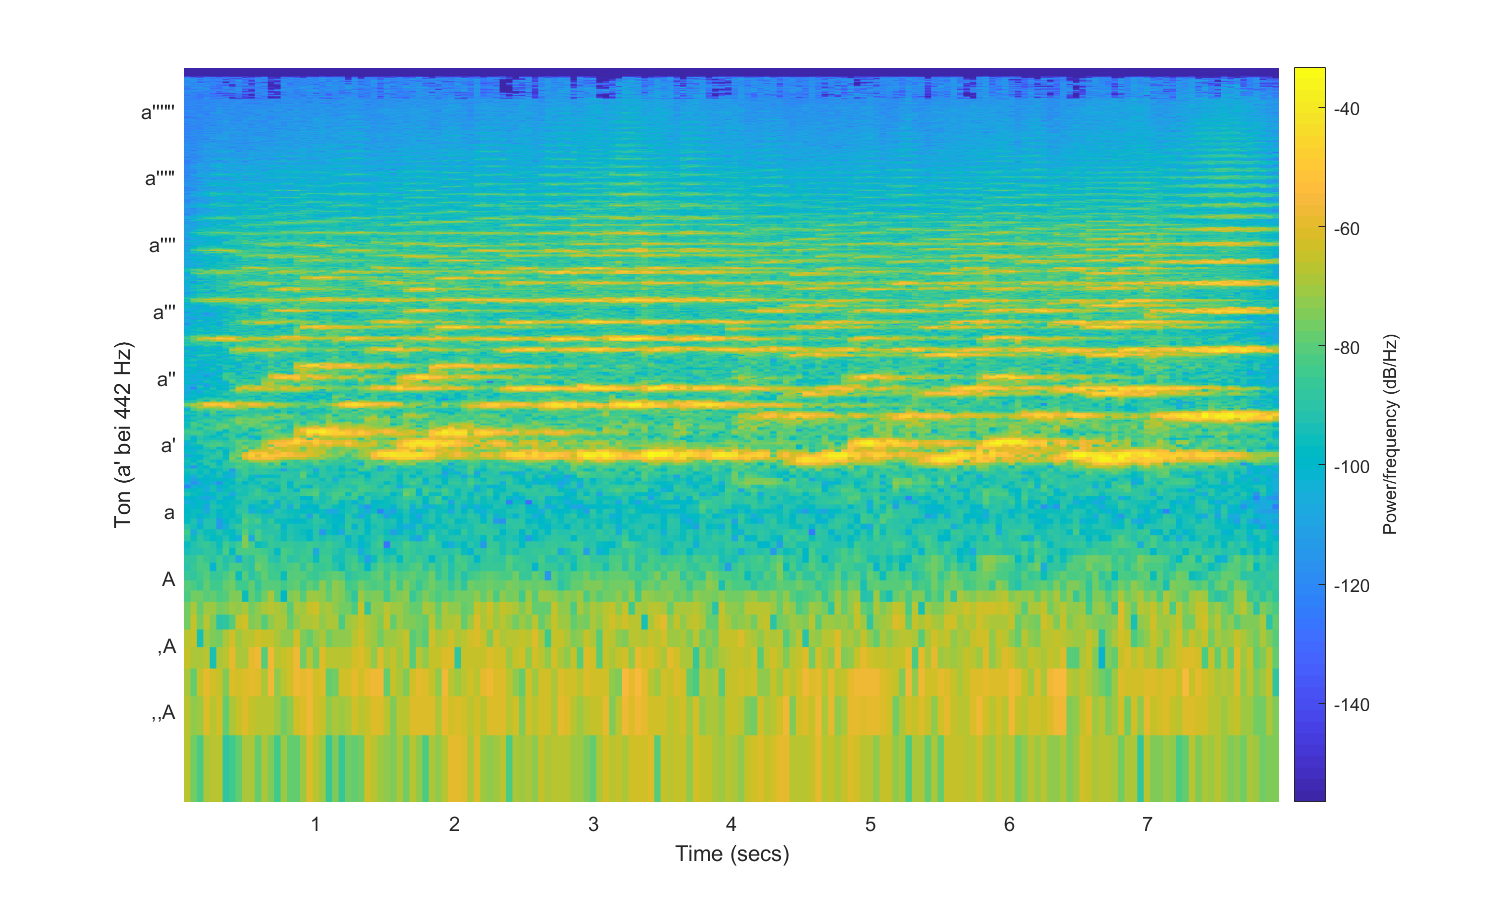

[y0,Fs]=audioread(musicname);
t = linspace(0, length(y0)/Fs, length(y0)); % so we can plot it

y1 = filt(y0);

audio1 = audioplayer(y0, Fs);
audio2 = audioplayer(y1, Fs);

myspec(y0,Fs,4096);

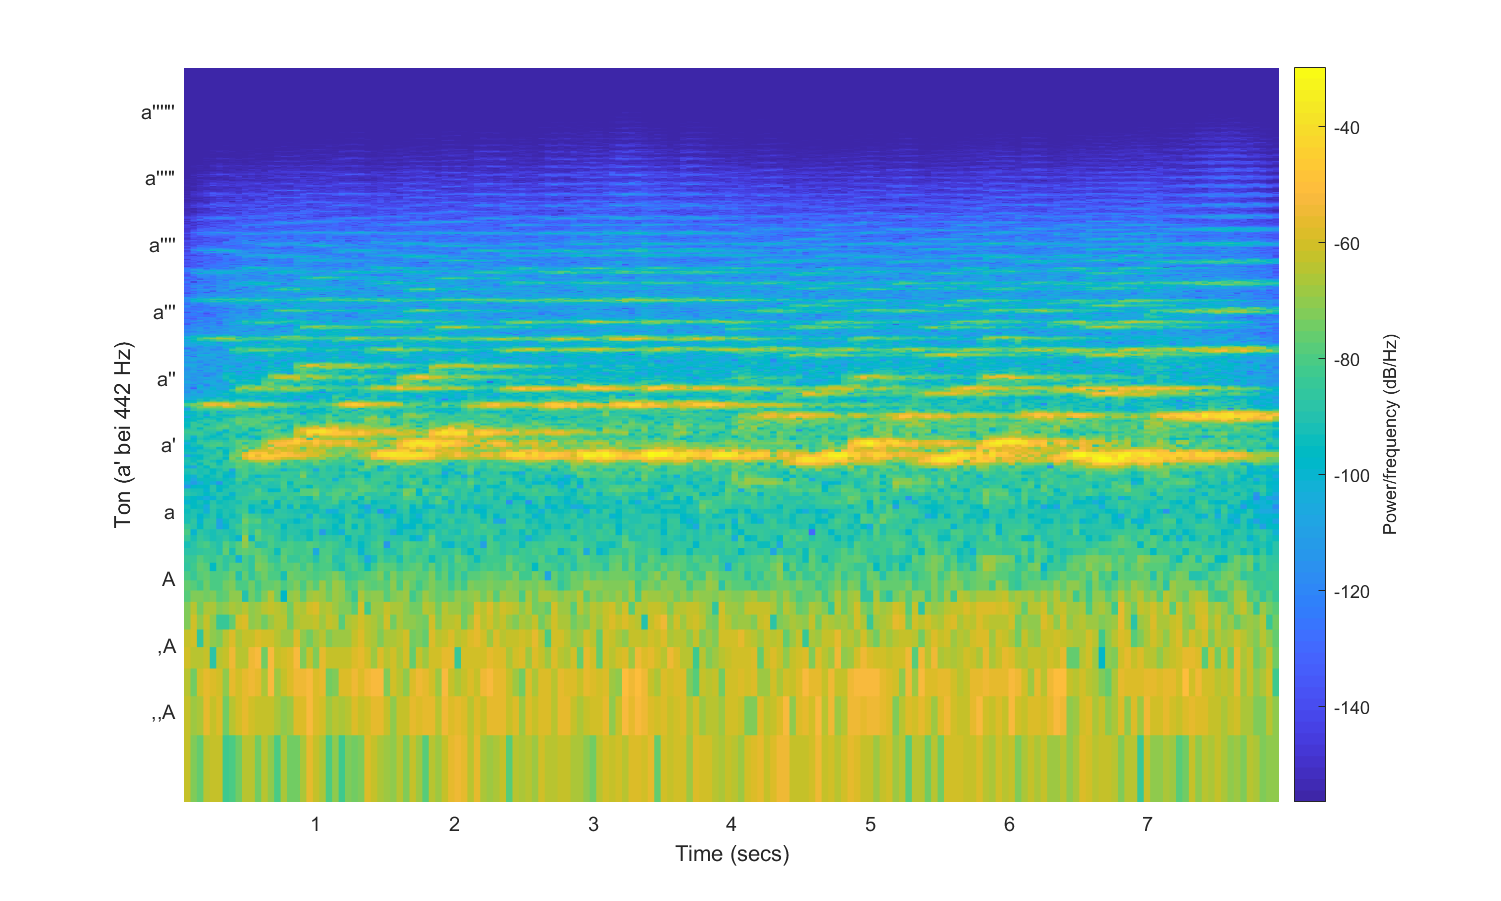

myspec(y1, Fs, 4096);

Now play both files:

play(audio1);

play(audio2);

Plot both waves:

plot(t, wave, 'r'); hold on

Undefined function or variable 'wave'.

plot(t, wave2, 'b'); 

The filter function from dsvGl Uebung 3.5

function y = filt(x)
    d0 = 1;
    d1 = 2;
    d2 = 1;
    c1 = -1.937;
    c2 = 0.94;
    y = zeros(1, length(x)); % initialize array
    for k=1+2:length(x)      % with offset of 2
        y(k) = d0*x(k) + d1*x(k-1) + d2*x(k-2) - c1*y(k-1) - c2*y(k-2);
    end
    y = y./800;     % scale the whole array to match the loudness somehow
end

Definition der Spektrogramm-Funktion © Hanspi Schmid (siv - der_ballon.mlx)

function myspec(sound,Fs,N)
    fig = figure;
    fig.OuterPosition = [0 0 1000 600];
    spectrogram(sound,hanning(N),[],[],Fs,'yaxis')
    ax=gca;
    set(ax,'Yscale','log')
    ax.YTick=2.^[-4 -3 -2 -1 0 1 2 3 4 5]*0.442;
    ax.YTickLabel={',,A',',A','A','a',"a'","a''","a'''","a''''","a'''''","a''''''"};
    ax.YLabel.String = "Ton (a' bei 442 Hz)";
end